clc
close all
options = simset('SrcWorkspace','current'); % Execute le circuit
out = sim('simulink_miroir_de_courant',[],options);

out =   Simulink.SimulationOutput:

               Diff_Vc1: [1x1 struct] 
               Diff_Vc2: [1x1 struct] 
              Diff_Vout: [1x1 struct] 
             Miroir_Vc1: [1x1 struct] 
             Miroir_Vc2: [1x1 struct] 
            Miroir_Vout: [1x1 struct] 
                   tout: [250x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


save variable out

## TP2

**Théorie**

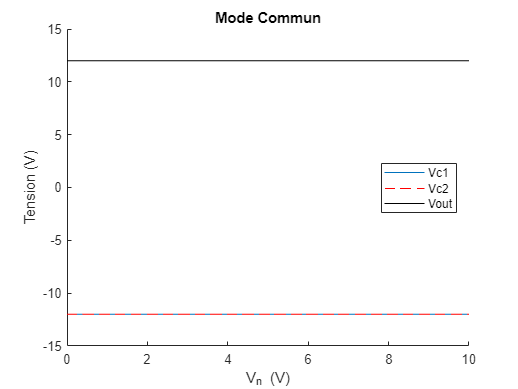

figure
hold on
% plot(out.Vc1.time,out.Vc1.signals.values,'k')
% plot(out.Vc2.time,out.Vc2.signals.values,'--r')
plot(out.Miroir_Vc1.time,out.Miroir_Vc1.signals.values)
plot(out.Miroir_Vc2.time,out.Miroir_Vc2.signals.values,'--r')
plot(out.Miroir_Vout.time,out.Miroir_Vout.signals.values,'k')
legend('Vc1','Vc2','Vout','location','best')
title('Mode Commun')
xlabel("V_i_n (V)")
ylabel("Tension (V)")
hold off

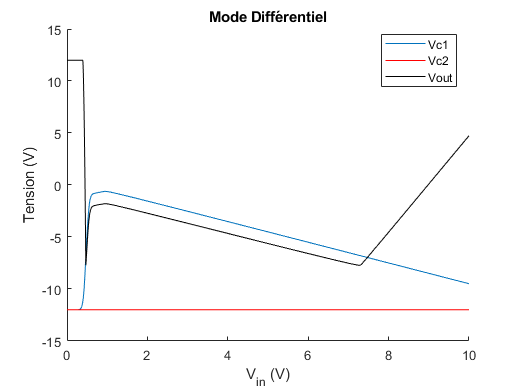


figure
hold on
plot(out.Diff_Vc1.time,out.Diff_Vc1.signals.values)
plot(out.Diff_Vc2.time,out.Diff_Vc2.signals.values,'r')
plot(out.Diff_Vout.time,out.Diff_Vout.signals.values,'k')
legend('Vc1','Vc2','Vout','location','best')
title('Mode Différentiel')
xlabel("V_i_n (V)")
ylabel("Tension (V)")
hold off

**Pratique**

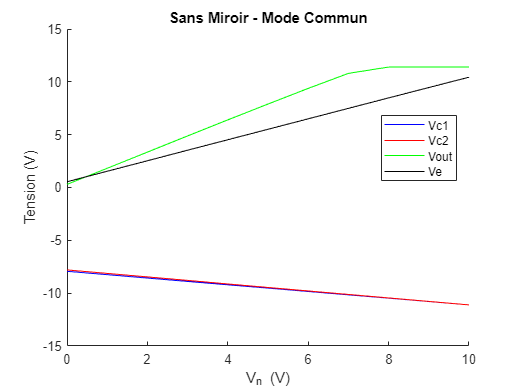

Vin=0:1:10;
%------ Montage sans miroir de courant
% Mode Commun
Vc1=[-7.93 -8.25 -8.57 -8.89 -9.21 -9.52 -9.84 -10.16 -10.47 -10.79 -11.11];
Vc2=[-7.80 -8.13 -8.46 -8.79 -9.13 -9.46 -9.79 -10.12 -10.45 -10.78 -11.11];
Vout=[296e-3 1.821 3.35 4.88 6.40 7.90 9.38 10.80 11.40 11.40 11.40 ];
Ve=[544e-3 1.538 2.53 3.53 4.52 5.51 6.50 7.49 8.48 9.46 10.44];

figure
hold on
plot(Vin,Vc1,'b')
plot(Vin,Vc2,'r')
plot(Vin,Vout,'g')
plot(Vin,Ve,'k')
legend('Vc1','Vc2','Vout','Ve','location','best')
title('Sans Miroir - Mode Commun')
xlabel("V_i_n (V)")
ylabel("Tension (V)")


% Mode Différentiel


%------ Montage avec miroir de courant
% Mode Commun


% Mode Différentiel